# 第一周作业：含充放电互斥约束的配电网储能日前优化调度

课程名称：《储能优化配置与调度技术》课程设计 储能231 / 梁宏熙 / 206231315。本人目标A，另比较同一条件下的B/C。

## 0. 模板使用说明与核心数学模型

**使用说明**：

- 请将本模板复制到 `ESS-Course-Submissions` 仓库下你的 【学号_姓名拼音】 文件夹中；

- 重命名为 【姓名拼音_学号_Week1.mlx】，并修改第 2 节中的 `Stu_ID` 为本人真实 9 位学号；

- 仔细阅读各节的 LaTeX 数学模型说明，在标有 `% 【已完成】` 的代码块处补全核心建模语句，并导出对应的 `.m` 纯文本脚本一并提交。

**核心数学模型**：

**1) 储能系统荷电状态（SoC）动态递推方程与充放电互斥约束**（已知单站额定功率 $P_i^{\mathrm{rated}}$、额定容量 $E_i^{\mathrm{rated}}$ 为常数，引入二进制互斥变量 $u_{i,t}^{\mathrm{ch}} \in \{0,1\}$）：


$$\mathrm{SoC}_{i,t} = \mathrm{SoC}_{i,t-1} + \frac{\eta_{\mathrm{ch}} P_{i,t}^{\mathrm{ch}}
 \Delta t}{E_i^{\mathrm{rated}}} - \frac{P_{i,t}^{\mathrm{dis}} \Delta t}{\eta_{\mathrm{dis}}
 E_i^{\mathrm{rated}}}, \quad \mathrm{SoC}_{\min} \le \mathrm{SoC}_{i,t} \le
 \mathrm{SoC}_{\max}$$



$$0 \le P_{i,t}^{\mathrm{ch}} \le u_{i,t}^{\mathrm{ch}} P_i^{\mathrm{rated}},
 \quad 0 \le P_{i,t}^{\mathrm{dis}} \le \left(1 - u_{i,t}^{\mathrm{ch}}\right)
 P_i^{\mathrm{rated}}, \quad u_{i,t}^{\mathrm{ch}} \in \{0,1\}$$


**2) 配电网 DistFlow 支路潮流与旋转二阶锥松弛方程**（令 $U_{i,t} = V_{i,t}^2, L_{ij,t} = I_{ij,t}^2$）：


$$P_{ij,t} - r_{ij} L_{ij,t} - \sum_{k\in\delta(j)} P_{jk,t} = P_{j,t}^{\mathrm{load}}
 - P_{j,t}^{\mathrm{pv}} + P_{j,t}^{\mathrm{ch}} - P_{j,t}^{\mathrm{dis}}$$



$$Q_{ij,t} - x_{ij} L_{ij,t} - \sum_{k\in\delta(j)} Q_{jk,t} = Q_{j,t}^{\mathrm{load}}$$



$$U_{j,t} = U_{i,t} - 2\left(r_{ij} P_{ij,t} + x_{ij} Q_{ij,t}\right) + \left(r_{ij}^2
 + x_{ij}^2\right) L_{ij,t}$$



$$\sqrt{\left(2P_{ij,t}\right)^2 + \left(2Q_{ij,t}\right)^2 + \left(L_{ij,t}
 - U_{i,t}\right)^2} \le L_{ij,t} + U_{i,t}, \quad \left(V_{\min}\right)^2 \le
 U_{i,t} \le \left(V_{\max}\right)^2$$


clear; clc; close all;
work_dir = fileparts(mfilename('fullpath'));
addpath(work_dir);
case_dir = week1_environment(work_dir);
yalmip('clear');
Student = struct('Name','梁宏熙','Pinyin','lianghongxi','Class','储能231','ID',206231315);

## 1. 自动检测算例库是否已在 MATLAB 搜索路径中

if ~exist('case_nongcun.m', 'file')
    % 若不在路径中，弹窗提示学生选择一次本地的 ESS-Course-Materials/cases 文件夹
    case_dir = uigetdir(pwd, '请选择教学资源库中的 cases 文件夹路径');
    addpath(case_dir);
end

## 2. 学号映射与网络参数读取

**【学生修改区】**：请将下方 `Stu_ID` 修改为你本人的 9 位学号！程序将根据末两位 $\mathrm{XY}$ 自动计算负荷缩放乘子 $\alpha = 1 + 0.002 \times \mathrm{XY}$ 并分配专属算例。

Stu_ID  = 206231315;
XY      = mod(Stu_ID, 100);
X_digit = floor(XY / 10);
Y_digit = mod(XY, 10);
alpha   = 1 + 0.002 * XY;

if ismember(Y_digit, [0, 1, 2, 3])
    case_name = 'case_nongcun';
elseif ismember(Y_digit, [4, 5, 6])
    case_name = 'case_chengshi_A';
else
    case_name = 'case_kaifaqu_A';
end
mpc = loadcase(fullfile(case_dir,[case_name '.m']));
load(fullfile(case_dir,'profiles_24h.mat'));
dt = 1;

if ismember(X_digit, [0, 1, 2])
    ess_buses  = [4, 9, 14];
    model_type = 'A'; % 模型 A：最大化新能源消纳（含微网损正则项）
elseif ismember(X_digit, [3, 4, 5])
    ess_buses  = [5, 11, 16];
    model_type = 'B'; % 模型 B：最小化全网有功网损
else
    ess_buses  = [6, 13, 17];
    model_type = 'C'; % 模型 C：最小化主网购电成本
end
pv_buses = ess_buses;
assigned_objective = model_type;
assert(T==24 && size(mpc.branch,1)==size(mpc.bus,1)-1,'需要24时段辐射状网络。');
assert(isequal(mpc.bus(:,1),(1:size(mpc.bus,1))'),'节点编号必须与矩阵行号一致。');
fprintf('储能231 梁宏熙 | 学号 %d | %s | 负荷倍率 %.3f | 目标 %s | 节点 %s\n',...
    Stu_ID,case_name,alpha,model_type,mat2str(ess_buses));

储能231 梁宏熙 | 学号 206231315 | case_chengshi_A | 负荷倍率 1.030 | 目标 A | 节点 [4 9 14]


## 3. 标幺值基准转换与设备参数设置

Sbase = mpc.baseMVA;
N_bus = size(mpc.bus, 1);
N_br  = size(mpc.branch, 1);
N_ess = length(ess_buses);
N_pv  = length(pv_buses);

fbus = mpc.branch(:, 1);
tbus = mpc.branch(:, 2);
r_br = mpc.branch(:, 3);
x_br = mpc.branch(:, 4);

Pd_pu       = (mpc.bus(:, 3) * alpha / Sbase) * load_curve_pu';
Qd_pu       = (mpc.bus(:, 4) * alpha / Sbase) * load_curve_pu';
P_pv_max_pu = (1.2 / Sbase) * repmat(pv_curve_pu', N_pv, 1);

P_ess_rated_pu = 1.5 / Sbase; % 单站固定额定功率 1.5 MW (标幺值)
E_ess_rated_pu = 3.0 / Sbase; % 单站固定额定容量 3.0 MWh (标幺值)
eta_ch  = 0.90;
eta_dis = 0.95;
SoC_min = 0.20;
SoC_max = 0.80;
SoC_0   = 0.50;

## 4. 声明 YALMIP 决策变量

U_bus  = sdpvar(N_bus, T, 'full'); % 节点电压平方 U_{i,t} = V_{i,t}^2
L_br   = sdpvar(N_br,  T, 'full'); % 支路电流平方 L_{ij,t} = I_{ij,t}^2
P_br   = sdpvar(N_br,  T, 'full'); % 支路首端有功功率 (p.u.)
Q_br   = sdpvar(N_br,  T, 'full'); % 支路首端无功功率 (p.u.)
P_grid = sdpvar(1,     T, 'full'); % 关口有功功率 (p.u.)
Q_grid = sdpvar(1,     T, 'full'); % 关口无功功率 (p.u.)
P_ch   = sdpvar(N_ess, T, 'full'); % 储能充电有功功率 (p.u.)
P_dis  = sdpvar(N_ess, T, 'full'); % 储能放电有功功率 (p.u.)
u_ch   = binvar(N_ess, T, 'full'); % 储能充放电互斥二进制变量 u_{i,t}^{ch} \in {0,1}
SoC    = sdpvar(N_ess, T, 'full'); % 储能荷电状态 SoC_{i,t}
P_pv   = sdpvar(N_pv,  T, 'full'); % 分布式光伏实际出力 (p.u.)

## 5. 构建约束条件

## 5.1 储能充放电互斥与分布式光伏运行约束

Constraints = [];
Constraints = [Constraints, 0 <= P_ch  <= P_ess_rated_pu * u_ch];
Constraints = [Constraints, 0 <= P_dis <= P_ess_rated_pu * (1 - u_ch)];
Constraints = [Constraints, SoC_min <= SoC <= SoC_max];
Constraints = [Constraints, SoC(:, T) == SoC_0];
Constraints = [Constraints, 0 <= P_pv <= P_pv_max_pu];

for t = 1:T
    if t == 1
        soc_prev = repmat(SoC_0, N_ess, 1);
    else
        soc_prev = SoC(:, t - 1);
    end
    % 采用本时段末SoC；初始和日末均为0.50，dt=1 h。
    Constraints = [Constraints, SoC(:, t) == soc_prev + ...
        (eta_ch * P_ch(:, t) - P_dis(:, t) / eta_dis) * dt / E_ess_rated_pu];
end

## 5.2 节点功率平衡与 DistFlow 二阶锥潮流约束

A_from  = sparse(fbus, 1:N_br, 1, N_bus, N_br);
A_to    = sparse(tbus, 1:N_br, 1, N_bus, N_br);
A_ess   = sparse(ess_buses, 1:N_ess, 1, N_bus, N_ess);
A_pv    = sparse(pv_buses,  1:N_pv,  1, N_bus, N_pv);
A_slack = sparse(1, 1, 1, N_bus, 1);

P_loss_br = diag(r_br) * L_br;
Q_loss_br = diag(x_br) * L_br;

Constraints = [Constraints, A_to * (P_br - P_loss_br) - A_from * P_br + ...
    A_slack * P_grid + A_pv * P_pv + A_ess * (P_dis - P_ch) == Pd_pu];
Constraints = [Constraints, A_to * (Q_br - Q_loss_br) - A_from * Q_br + ...
    A_slack * Q_grid == Qd_pu];

Constraints = [Constraints, U_bus(1, :) == 1.0];
Constraints = [Constraints, (0.95^2) <= U_bus(2:end, :) <= (1.05^2)];
Constraints = [Constraints, L_br >= 0];

for b = 1:N_br
    i = fbus(b);
    j = tbus(b);
    % cone 等价于 P^2+Q^2<=U_i*L；保留电压方程中的损耗项。
    Constraints = [Constraints, U_bus(j, :) == U_bus(i, :) - ...
        2 * (r_br(b) * P_br(b, :) + x_br(b) * Q_br(b, :)) + ...
        (r_br(b)^2 + x_br(b)^2) * L_br(b, :)];
    for t = 1:T
        % 等价缩放使L与U的数值尺度接近；乘积仍为L*U，未改变物理模型。
        cone_scale = Sbase;
        Constraints = [Constraints, cone([2 * P_br(b, t); 2 * Q_br(b, t); ...
            cone_scale*L_br(b, t) - U_bus(i, t)/cone_scale], ...
            cone_scale*L_br(b, t) + U_bus(i, t)/cone_scale)];
    end
end

## 6. 构建目标函数并调用 MISOCP 求解器 (MOSEK / Gurobi)

本模型同时包含充放电互斥二进制变量 $u_{i,t}^{\mathrm{ch}}$ 与支路二阶锥约束，属于混合整数二阶锥规划（MISOCP），需调用 MOSEK 或 Gurobi 求解。若使用 CVX 随附的 MOSEK，请仅将 `cvx/mosek` 子文件夹加入 MATLAB 路径（|addpath(genpath('.../cvx/mosek'))|），切勿运行 `cvx_setup` 或添加 `cvx` 根目录。

Total_Loss_MWh    = Sbase * sum(sum(P_loss_br)) * dt;
Total_Curtail_MWh = Sbase * sum(sum(P_pv_max_pu - P_pv)) * dt;
Total_Cost_Yuan   = sum((Sbase * P_grid') .* price_MWh) * dt;

% A附加0.01*网损以促进松弛收紧；B辅助项严格沿用课件的标幺功率表达式。
if strcmp(model_type, 'A')
    Objective = Total_Curtail_MWh + 1e-2 * Total_Loss_MWh;
elseif strcmp(model_type, 'B')
    Objective = Total_Loss_MWh + 1e-4 * sum(sum(P_ch + P_dis));
else
    Objective = Total_Cost_Yuan;
end

solver_name = 'gurobi';
ops = sdpsettings('solver',solver_name,'verbose',0,'savesolveroutput',1);
ops.gurobi.TimeLimit=300; ops.gurobi.Threads=4; ops.gurobi.Seed=15;
ops.gurobi.MIPGap=1e-6; ops.gurobi.MIPGapAbs=1e-8;
ops.gurobi.FeasibilityTol=1e-9; ops.gurobi.IntFeasTol=1e-9;
ops.gurobi.OptimalityTol=1e-8; ops.gurobi.BarQCPConvTol=1e-10;
ops.gurobi.NumericFocus=1;
objectives=struct('A',Total_Curtail_MWh+0.01*Total_Loss_MWh,...
    'B',Total_Loss_MWh+1e-4*sum(sum(P_ch+P_dis)),'C',Total_Cost_Yuan);
% 最后求解本人目标，使后续value(...)和所有本人图形均对应分配的模型。
sequence=[setdiff('ABC',assigned_objective,'stable'),assigned_objective];
Runs=struct;
for model_type=sequence
    fprintf('\n正在求解目标 %s ...\n',model_type);
    ops.gurobi.LogFile=fullfile(work_dir,sprintf('Week1_Gurobi_%s.log',model_type));
    % 连续松弛仅用于产生初值，最终仍求解含全部二进制变量的MISOCP。
    relaxed_ops=ops;relaxed_ops.relax=1;relaxed_ops.gurobi.TimeLimit=60;
    relaxation=optimize(Constraints,objectives.(model_type),relaxed_ops);
    if relaxation.problem==0
        relaxed_charge=value(P_ch);relaxed_discharge=value(P_dis);
        if max(min(relaxed_charge,relaxed_discharge),[],'all')*Sbase<=1e-6
            assign(u_ch,double(relaxed_charge>=relaxed_discharge));ops.usex0=1;
        else
            ops.usex0=0;
        end
    else
        ops.usex0=0;
    end
    solve_clock=tic;sol=optimize(Constraints,objectives.(model_type),ops);solve_seconds=toc(solve_clock);
    assert(sol.problem==0,'目标%s求解失败：%s',model_type,sol.info);
    solver_result=sol.solveroutput.result;
    assert(strcmp(solver_result.status,'OPTIMAL'),'目标%s未返回OPTIMAL。',model_type);
    d=struct('mpc',mpc,'Stu_ID',Stu_ID,'case_name',case_name,'model_type',model_type,...
        'solver',solver_name,'solve_seconds',solve_seconds,'Sbase',Sbase,'dt',dt,...
        'ess_buses',ess_buses,'pv_buses',pv_buses,'PratedMW',1.5,'EratedMWh',3,...
        'SoC0',SoC_0,'SoCmin',SoC_min,'SoCmax',SoC_max,'eta_ch',eta_ch,'eta_dis',eta_dis,...
        'price_MWh',price_MWh,'PloadMW',Pd_pu*Sbase,'QloadMvar',Qd_pu*Sbase,...
        'PpvMW',Sbase*value(P_pv),'PpvMaxMW',P_pv_max_pu*Sbase,...
        'PchMW',Sbase*value(P_ch),'PdisMW',Sbase*value(P_dis),...
        'SoC',value(SoC),'u',value(u_ch),'U',value(U_bus),'L',value(L_br),...
        'P',value(P_br),'Q',value(Q_br),'Pgrid',value(P_grid),'Qgrid',value(Q_grid));
    [report,v_ac]=week1_validate_dispatch(d);
    report.SolverStatus=solver_result.status;report.ObjectiveValue=solver_result.objval;
    report.ObjectiveBound=solver_result.objbound;report.MIPGap=solver_result.mipgap;
    assert(report.StorageConstraintsPassed && report.LinearConstraintsPassed,...
        '目标%s的储能或线性约束校验未通过。',model_type);
    if model_type~='C',assert(report.Passed,'目标%s的锥松弛或交流校验未通过。',model_type);end
    Runs.(model_type)=struct('Data',d,'Check',report,'VAC',v_ac);
    save(fullfile(work_dir,'Week1_solve_checkpoint.mat'),'Runs');
    fprintf('%s: status=%s, objective=%.9g, mipgap=%.3g, time=%.2fs\n',...
        model_type,report.SolverStatus,report.ObjectiveValue,report.MIPGap,solve_seconds);
    fprintf('弃光%.6f MWh；交流网损%.6f MWh；锥间隙%.3e；交流电压[%.6f,%.6f] p.u.\n',...
        report.Curtailment_MWh,report.ACLineLoss_MWh,report.MaxConeGap,report.MinACVoltage,report.MaxACVoltage);
end


正在求解目标 B ...


B: status=OPTIMAL, objective=0.152931654, mipgap=0, time=1.58s


弃光11.579595 MWh；交流网损0.152915 MWh；锥间隙6.660e-08；交流电压[0.971854,1.000000] p.u.



正在求解目标 C ...


C: status=OPTIMAL, objective=12944.0498, mipgap=0, time=1.57s


弃光0.000000 MWh；交流网损1.010779 MWh；锥间隙6.718e-09；交流电压[0.950000,1.047183] p.u.



正在求解目标 A ...


A: status=OPTIMAL, objective=0.00354986468, mipgap=0, time=30.20s


弃光0.000000 MWh；交流网损0.354348 MWh；锥间隙3.250e-06；交流电压[0.971849,1.017517] p.u.


model_type=assigned_objective;AssignedResults=Runs.(model_type);
Comparison=struct2table([Runs.A.Check,Runs.B.Check,Runs.C.Check]);
Comparison=Comparison(:,{'Objective','SolverStatus','ObjectiveValue','MIPGap','SolveSeconds',...
    'Curtailment_MWh','LineLoss_MWh','ACLineLoss_MWh','GridCost_Yuan','ACGridCost_Yuan',...
    'MaxConeGap','MinACVoltage','MaxACVoltage','MaxACVoltageError','Passed','TeachingCounterexample'});
disp(Comparison);

    Objective    SolverStatus    ObjectiveValue    MIPGap    SolveSeconds    Curtailment_MWh    LineLoss_MWh    ACLineLoss_MWh    GridCost_Yuan    ACGridCost_Yuan    MaxConeGap    MinACVoltage    MaxACVoltage    MaxACVoltageError    Passed    TeachingCounterexample
    _________    ____________    ______________    ______    ____________    _______________    ____________    ______________    _____________    _______________    __________    ____________    ____________    _________________    ______    ______________________

      {'A'}      {'OPTIMAL'}       0.0035499         0          30.198                0           0.35499          0.35435            16495             16495         3.2502e-06      0.97185          1.0175           4.924e-07        true              false         
      {'B'}      {'OPTIMAL'}         0.15293         0          1.5845            11.58           0.15292          0.15292            24842             24842         6.6598e-08      0.97185            

## 7. 二阶锥松弛精确性分析、交流潮流回代与《中国电机工程学报》规范绘图

请注意图片字体与符号规范：中文采用宋体，西文与数字采用 Times New Roman，变量符号采用斜体，单位与下标说明采用正体。

socp_gap=AssignedResults.Check.MaxConeGap;
simul_err_MW=AssignedResults.Check.MaxSimultaneousPower_MW;

V_socp_pu     = sqrt(value(U_bus));
V_ac_ess=AssignedResults.VAC;
Ploss_ac_MWh=AssignedResults.Check.ACLineLoss_MWh;
P_net_ess_MW  = Sbase * value(P_dis - P_ch);
P_pv_MW_val   = Sbase * value(P_pv);
max_ac_v_err = max(max(abs(V_socp_pu - V_ac_ess)));

fprintf('\n================ 第一周：配电网储能 MISOCP 优化调度结果 ================\n');


================ 第一周：配电网储能 MISOCP 优化调度结果 ================


fprintf('学号: %d | 算例: %s | 模型: %s | 求解器: %s\n', Stu_ID, case_name, model_type, solver_name);

学号: 206231315 | 算例: case_chengshi_A | 模型: A | 求解器: gurobi


fprintf('模型全天电能损耗: %.4f MWh | 交流潮流电能损耗: %.4f MWh | 弃光量: %.4f MWh | 关口购电成本: %.2f 元\n', ...
    value(Total_Loss_MWh), Ploss_ac_MWh, value(Total_Curtail_MWh), value(Total_Cost_Yuan));

模型全天电能损耗: 0.3550 MWh | 交流潮流电能损耗: 0.3543 MWh | 弃光量: -0.0000 MWh | 关口购电成本: 16495.17 元


fprintf('同时充放电最大重叠功率: %.2e MW | 最大二阶锥松弛间隙: %.2e p.u.\n', simul_err_MW, socp_gap);

同时充放电最大重叠功率: 0.00e+00 MW | 最大二阶锥松弛间隙: 3.25e-06 p.u.


fprintf('交流潮流节点电压范围: [%.4f, %.4f] p.u. | 模型与交流电压最大偏差: %.2e p.u.\n', ...
    min(V_ac_ess(:)), max(V_ac_ess(:)), max_ac_v_err);

交流潮流节点电压范围: [0.9718, 1.0175] p.u. | 模型与交流电压最大偏差: 4.92e-07 p.u.


assert(AssignedResults.Check.Passed,'本人目标必须通过储能、线性约束、锥松弛和交流电压检查。');
fprintf('========================================================================\n');

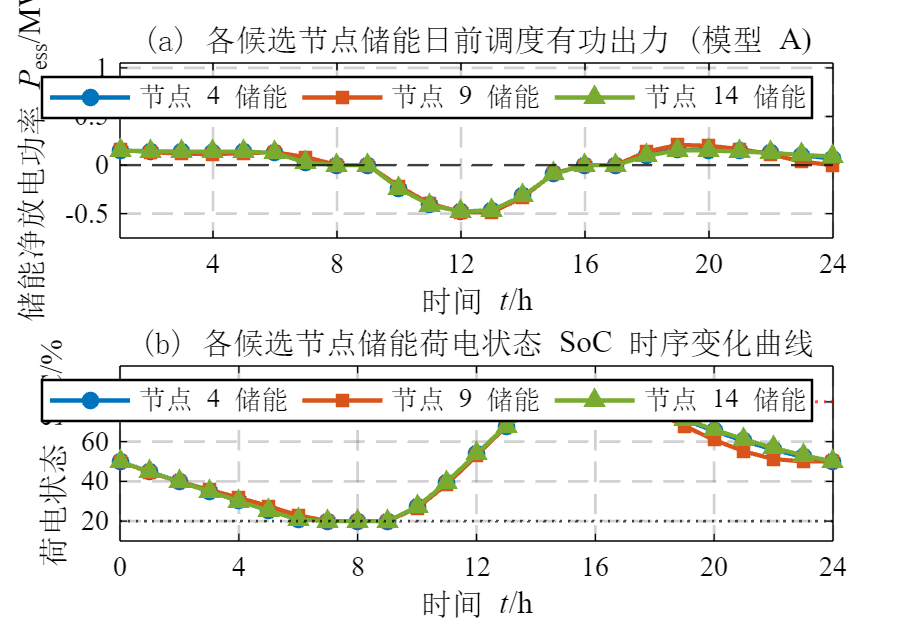


P_net_MW_val = Sbase * value(P_dis - P_ch)';
SoC_pct_val  = value(SoC)' * 100;
line_styles  = {'-o', '-s', '-^'};
colors       = [0.00, 0.45, 0.74; 0.85, 0.33, 0.10; 0.47, 0.67, 0.19];

fig1 = figure('Name', '配电网储能日前MISOCP调度结果', 'Color', 'w', 'Position', [120, 100, 720, 500]);
if isprop(fig1, 'Theme') && exist('theme', 'file') == 2, theme(fig1, 'light'); end

subplot(2, 1, 1);
hold on;
for k = 1:N_ess
    plot(1:T, P_net_MW_val(:, k), line_styles{k}, 'Color', colors(k, :), ...
        'LineWidth', 1.6, 'MarkerSize', 5, 'MarkerFaceColor', colors(k, :));
end
yline(0, '--k', 'LineWidth', 0.9);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'FontName', 'Times New Roman', 'FontSize', 10.5, 'LineWidth', 1.0, ...
    'Box', 'on', 'TickDir', 'in', 'XTick', 0:4:24, 'GridLineStyle', '--', 'GridAlpha', 0.3, 'GridColor', [0.4, 0.4, 0.4]);
xlim([1, T]);
xticks(4:4:T); xticklabels(string(4:4:T));
ylim([min([P_net_MW_val(:); -0.5]) - 0.25, max([P_net_MW_val(:); 0.5]) + 0.55]);
xlabel('\fontname{宋体}时间 \fontname{Times New Roman}{\itt}\rm{/h}', 'FontSize', 11.5, 'Color', 'k', 'Interpreter', 'tex');
ylabel('\fontname{宋体}储能净放电功率 \fontname{Times New Roman}{\itP}_{\rm{ess}}\rm{/MW}', 'FontSize', 11.5, 'Color', 'k', 'Interpreter', 'tex');
title(sprintf('\\fontname{宋体}(a) 各候选节点储能日前调度有功出力 (模型 \\fontname{Times New Roman}%s)', model_type), ...
    'FontSize', 11.5, 'FontWeight', 'normal', 'Color', 'k', 'Interpreter', 'tex');
leg_str_a = arrayfun(@(b) sprintf('\\fontname{宋体}节点 \\fontname{Times New Roman}%d \\fontname{宋体}储能', b), ...
    ess_buses, 'UniformOutput', false);
leg1 = legend(leg_str_a, 'Location', 'north', 'Orientation', 'horizontal', 'FontSize', 10, 'Interpreter', 'tex', 'Box', 'on');
set(leg1, 'Color', 'w', 'TextColor', 'k', 'EdgeColor', 'k');
grid on;

subplot(2, 1, 2);
hold on;
for k = 1:N_ess
    plot(0:T, [SoC_0*100;SoC_pct_val(:, k)], line_styles{k}, 'Color', colors(k, :), ...
        'LineWidth', 1.6, 'MarkerSize', 5, 'MarkerFaceColor', colors(k, :));
end
yline(SoC_min * 100, ':k', 'LineWidth', 1.1);
yline(SoC_max * 100, ':r', 'LineWidth', 1.1);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'FontName', 'Times New Roman', 'FontSize', 10.5, 'LineWidth', 1.0, ...
    'Box', 'on', 'TickDir', 'in', 'XTick', 0:4:24, 'GridLineStyle', '--', 'GridAlpha', 0.3, 'GridColor', [0.4, 0.4, 0.4]);
xlim([0, T]);
xticks(0:4:T); xticklabels(string(0:4:T));
ylim([10, 98]);
xlabel('\fontname{宋体}时间 \fontname{Times New Roman}{\itt}\rm{/h}', 'FontSize', 11.5, 'Color', 'k', 'Interpreter', 'tex');
ylabel('\fontname{宋体}荷电状态 \fontname{Times New Roman}\rm{SoC}/%', 'FontSize', 11.5, 'Color', 'k', 'Interpreter', 'tex');
title('\fontname{宋体}(b) 各候选节点储能荷电状态 \fontname{Times New Roman}\rm{SoC} \fontname{宋体}时序变化曲线', ...
    'FontSize', 11.5, 'FontWeight', 'normal', 'Color', 'k', 'Interpreter', 'tex');
leg2 = legend(leg_str_a, 'Location', 'north', 'Orientation', 'horizontal', 'FontSize', 10, 'Interpreter', 'tex', 'Box', 'on');
set(leg2, 'Color', 'w', 'TextColor', 'k', 'EdgeColor', 'k');
grid on;

% 默认自动导出高质量白底 PNG (600 dpi)、矢量 PDF 与 MATLAB 源文件 FIG
exportgraphics(fig1,fullfile(work_dir,sprintf('Fig_Week1_Dispatch_%d.png',Stu_ID)), 'Resolution',600,'BackgroundColor','white');
exportgraphics(fig1,fullfile(work_dir,sprintf('Fig_Week1_Dispatch_%d.pdf',Stu_ID)), 'ContentType','vector','BackgroundColor','white');

savefig(fig1,fullfile(work_dir,sprintf('Fig_Week1_Dispatch_%d.fig',Stu_ID)));

## 8. 完整图形、逐时数据、独立校验及手算练习

同一1.2 MW/节点光伏场景下建立无储能交流基准。A/B/C共用相同约束， 按实际数值分析目标C；不直接照搬课件农村49节点算例的结论。

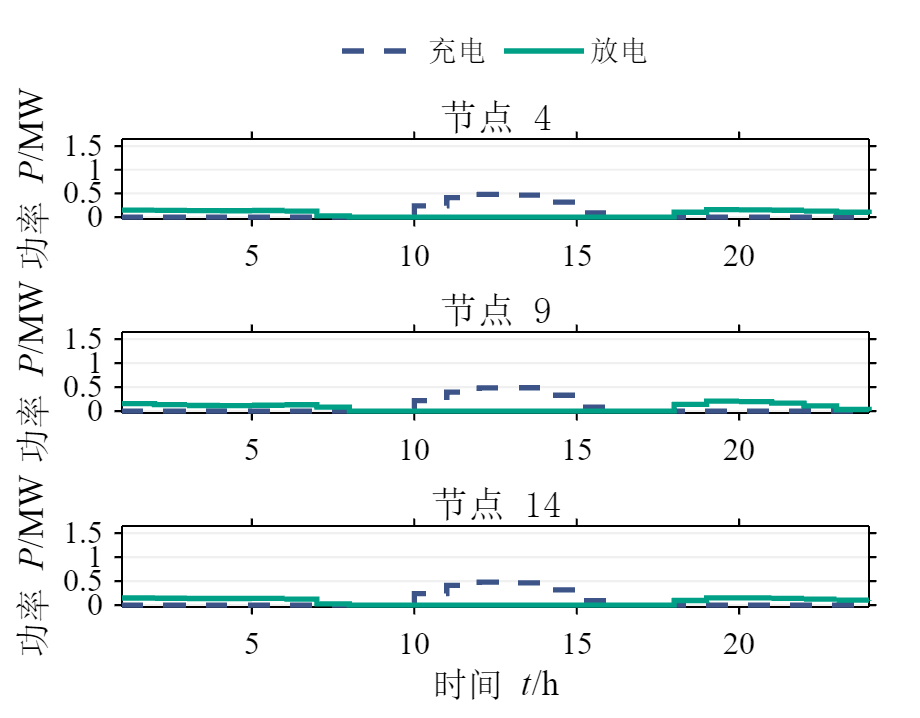

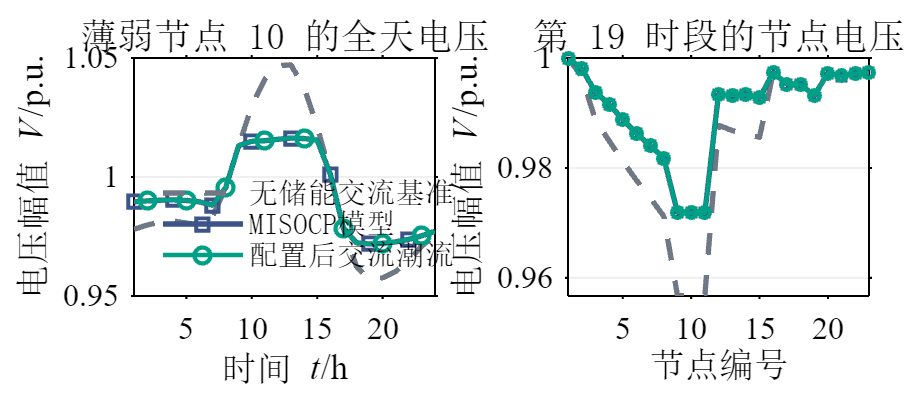

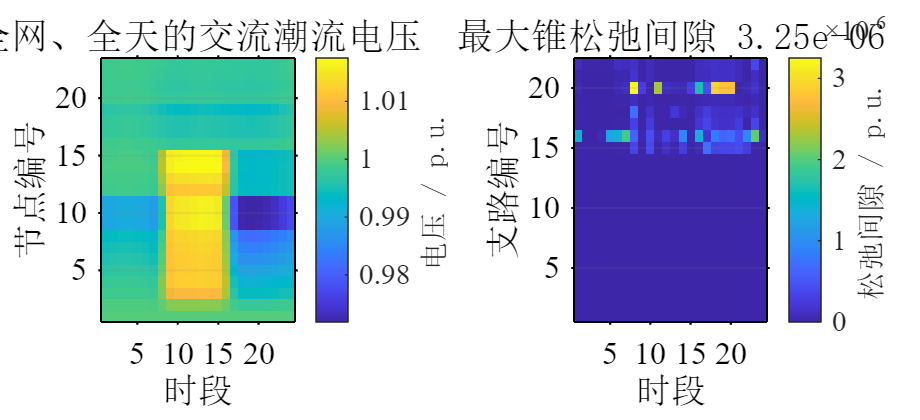

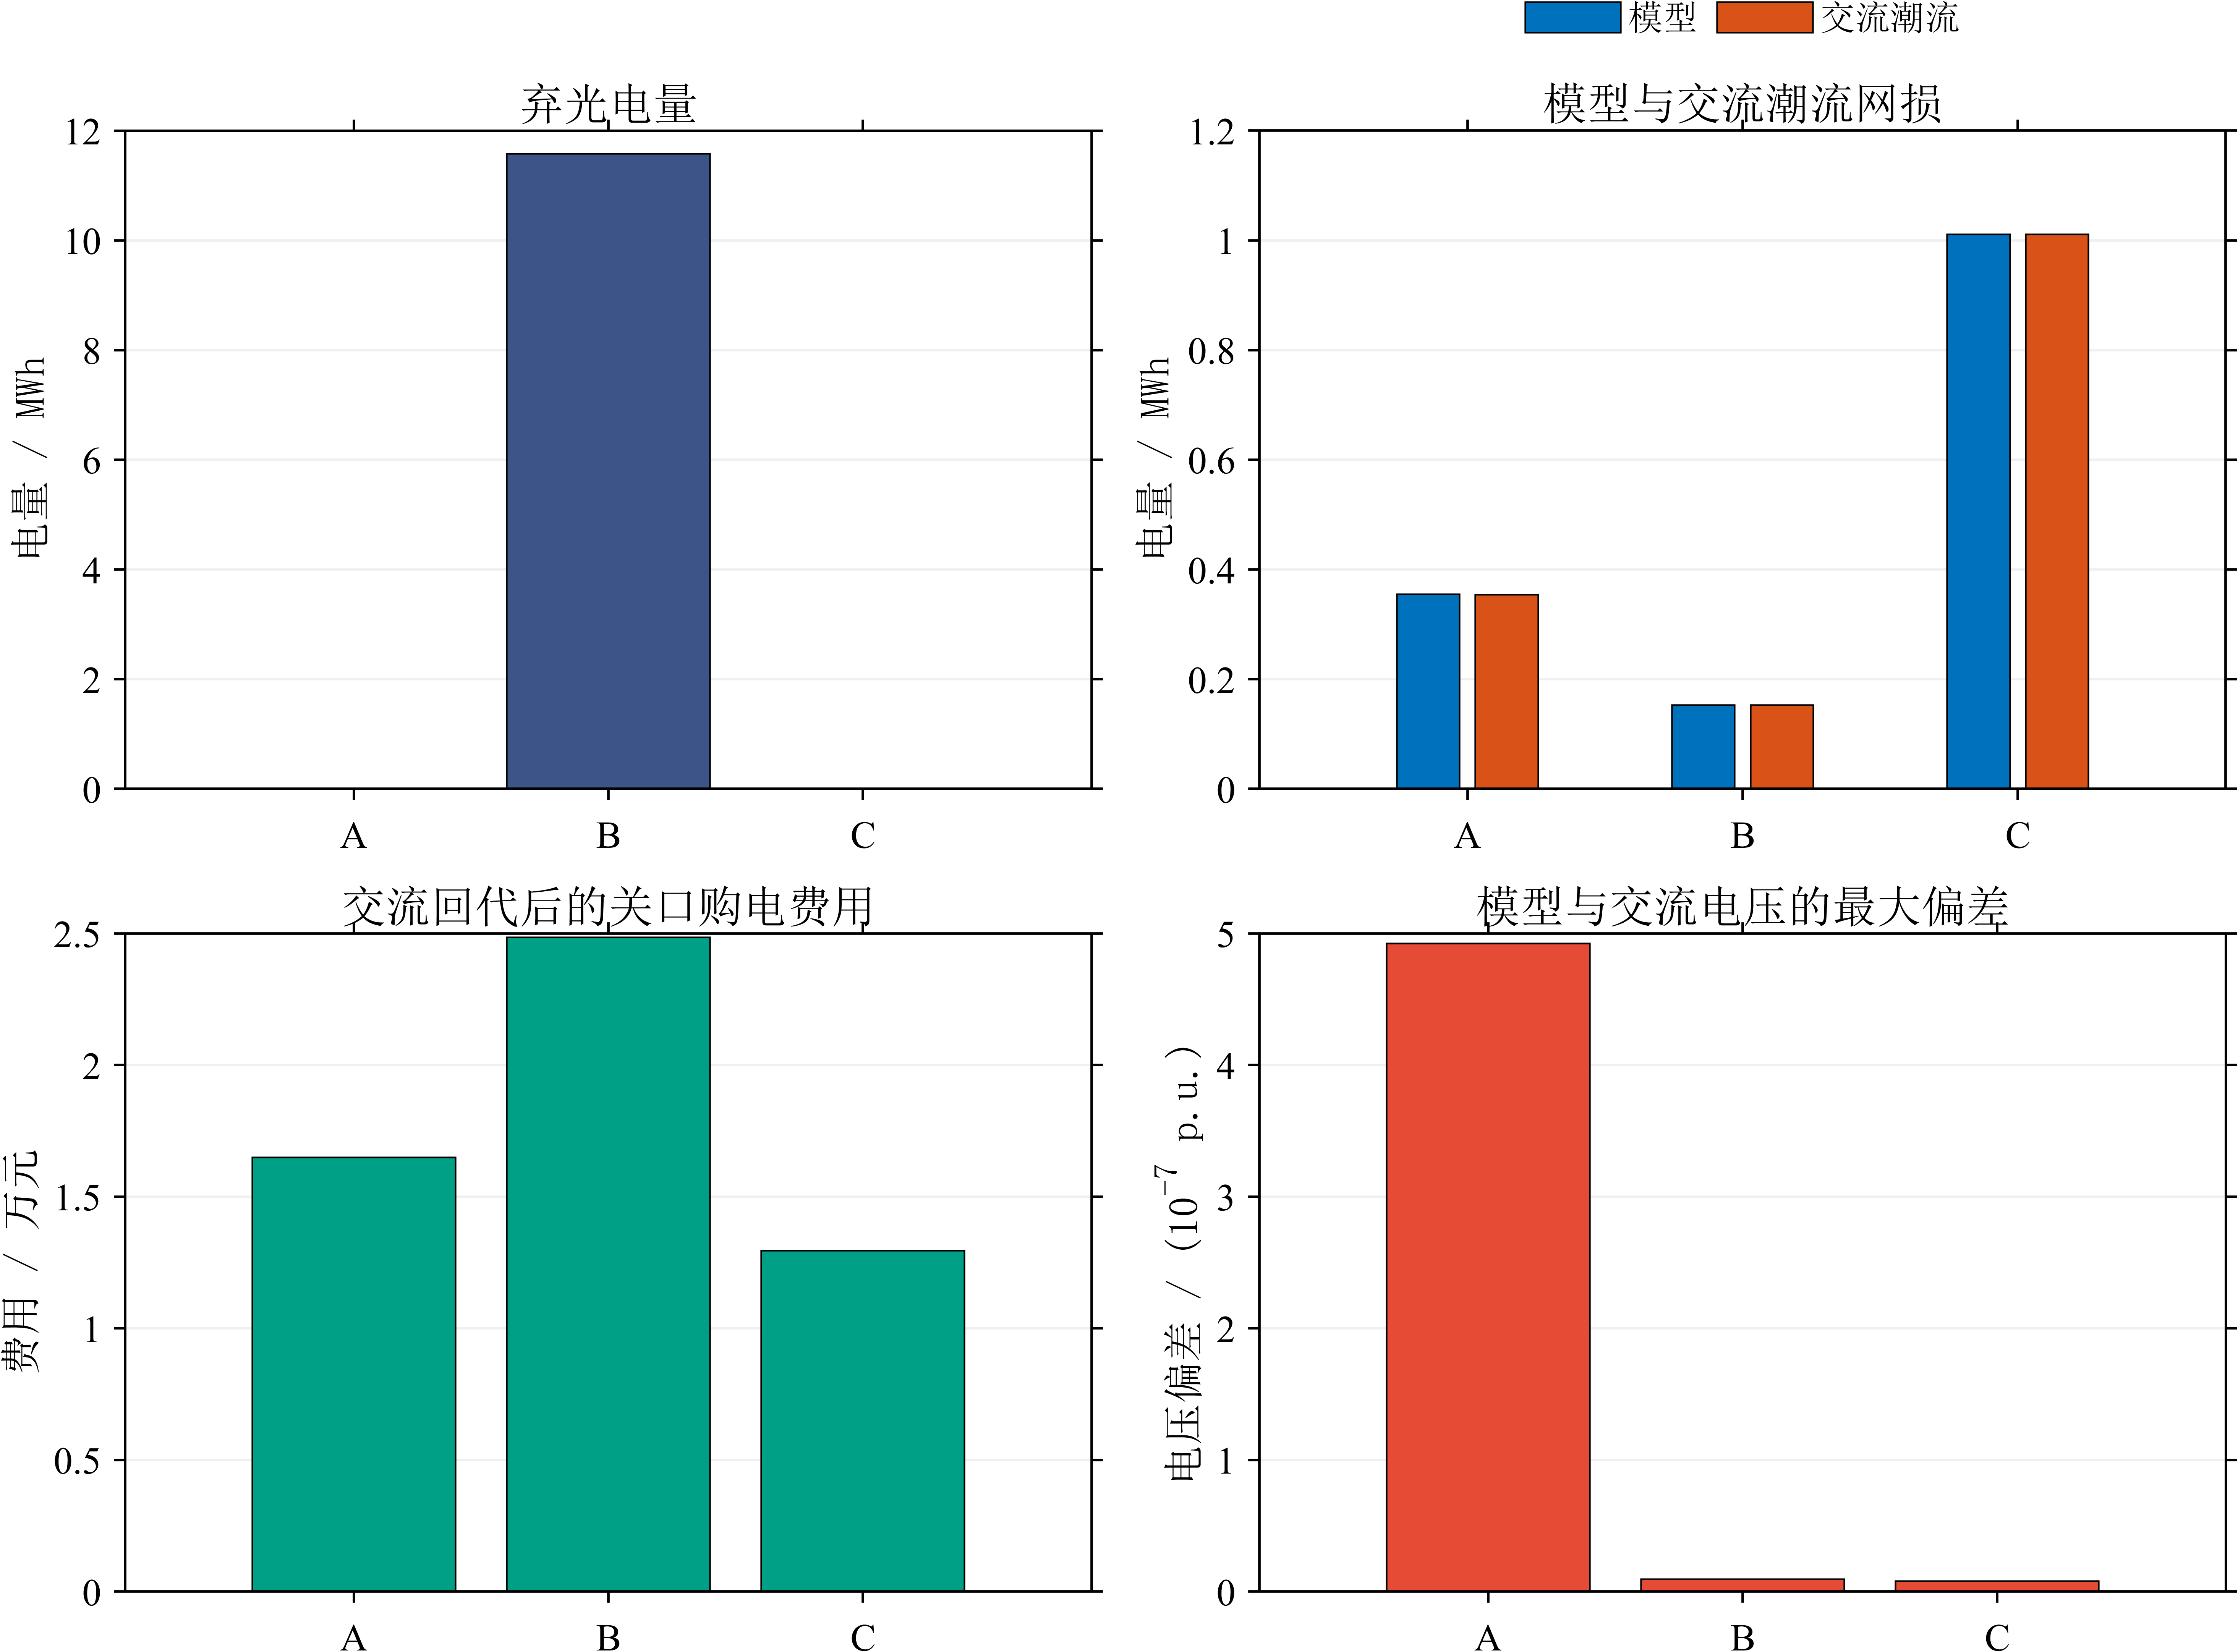

             Metric                Value       Tolerance    Passed
    _________________________    __________    _________    ______

    {'SimultaneousPower_MW' }             0      1e-06      true  
    {'IntegerError'         }             0      1e-06      true  
    {'SoCViolation'         }             0      1e-06      true  
    {'TerminalSoCError'     }             0      1e-06      true  
    {'EnergyBalance_MWh'    }    1.9429e-16      1e-06      true  
    {'PowerViolation_MW'    }             0      1e-05      true  
    {'PVViolation_MW'       }             0      1e-05      true  
    {'ActiveBalance_pu'     }    2.7374e-14      1e-07      true  
    {'ReactiveBalance_pu'   }    4.0161e-14      1e-07      true  
    {'VoltageEquation_pu'   }     1.918e-12      1e-07      true  
    {'ConeGap'              }    3.2502e-06      1e-05      true  
    {'ACVoltageViolation_pu'}             0      1e-06      true  
    {'ACConvergenceFailure' }             0          0      t

Summary=week1_export_analysis(work_dir,Student,Runs,Comparison,alpha);

gap_example=abs(1.00*0.02-0.10^2-0.05^2);
fprintf('课件手算：g=|1.00*0.02-0.10^2-0.05^2|=%.4f，存在严格松弛。\n',gap_example);

课件手算：g=|1.00*0.02-0.10^2-0.05^2|=0.0075，存在严格松弛。


fprintf('第一周完成，数据与图形保存于：%s\n',work_dir);

第一周完成，数据与图形保存于：D:\sum\study\D4\hello_word\ESS-Course-Submissions\206231315_lianghongxi
